#### Low Pass Filter

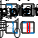

% LowPass

clc; close all; clear all;

M=28; 
N=2*M+1; % Filter Length
tw=1000; % Transition Width
Fs=10000; % Sampling Frequency
f=2000+tw/2; % fp(ideal)
Ts=1/Fs;
n=-M:M;

%w=window(@hamming,N); % Hamming Window
w=window(@blackman,N); % Blackman Window
%w=window(@rectwin,N); % Rectangular Window

wp=2*pi*f; % Passband Edge Frequency in rads^-1

h=zeros(1,N); 
h=sin(wp.*n.*Ts)./(n*pi);
h(round(length(h)/2))=wp*Ts/pi;

hn=w'.*h; % Impulse Response

N=20480;
Y=abs(fft(hn,N));

f=0:Fs/(N-1):Fs;

figure;

subplot(2,2,1)
plot(f,Y);
title('Magnitude Response of the LPF')
axis([0 Fs/2,0 1.1]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on;

subplot(2,2,2)
plot(f,Y);
title('Passband ripple of the LPF')
axis([0 Fs/2,0.999 1.001]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on;

subplot(2,2,3)
plot(f,Y);
title('Stopband ripple of the LPF')
axis([0 Fs/2, 0 0.001]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on;

subplot(2,2,4)
plot(f,Y); 
title('Transition width of the LPF')
hold on;
plot([2500-tw/2, 2500-tw/2], [0, 1], '-r');
plot([2500+tw/2, 2500+tw/2], [0, 1], '-r');
axis([0 Fs/2,0 1.1]);
xlabel('f(Hz)'); 
ylabel('|H(f)|');
grid on;
hold off;

#### High Pass Filter

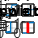

% HighPass

clc; close all; clear all;

M=27;
N=2*M+1;
tw=500;
Fs=8000;
f=2000-tw/2; % fp(ideal)
Ts=1/Fs;
n=-M:M;

w=window(@hamming,N); % Hamming Window
%w=window(@blackman,N); %Blackman Window
%w=window(@rectwin,N); % Rectangular Window

wp=2*pi*f;

h=zeros(1,N); 
h=0-sin(wp.*n.*Ts)./(n*pi);
h(round(length(h)/2))=1-wp*Ts/pi;

hn=w'.*h; %Impulse response

N=20480;
Y=abs(fft(hn,N));

f=0:Fs/(N-1):Fs;

figure;

subplot(2,2,1)
plot(f,Y);
title('Magnitude Response of the HPF')
axis([0 Fs/2,0 1.1]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on

subplot(2,2,2)
plot(f,Y);
title('Passband ripple of the HPF')
axis([0 Fs/2,0.99 1.01]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on;

subplot(2,2,3)
plot(f,Y);
title('Stopband ripple of the HPF')
axis([0 Fs/2, 0 0.01]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on;

subplot(2,2,4)
plot(f,Y); 
title('Transition width of the HPF')
hold on;
plot([1750-tw/2, 1750-tw/2], [0, 1], '-r');
plot([1750+tw/2, 1750+tw/2], [0, 1], '-r');
axis([0 Fs/2,0 1.1]);
xlabel('f(Hz)'); 
ylabel('|H(f)|');
grid on;
hold off;

#### Band Pass Filter

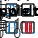

% BandPass

clc; close all; clear all;

M=36;
N=2*M+1;
tw=750;
Fs=16000;
f1=3000+tw/2;
f2=2000-tw/2;
Ts=1/Fs;
n=-36:36;

w=window(@hamming,N);

w1=2*pi*f1; 
w2=2*pi*f2;

h1=zeros(1,N); 
h1=sin(w1.*n.*Ts)./(n*pi);
h1(round(length(h1)/2))=w1*Ts/pi;

h2=zeros(1,N); 
h2=sin(w2.*n.*Ts)./(n*pi);
h2(round(length(h2)/2))=w2*Ts/pi;

h=h1-h2;

h=w'.*h;

N=20480;
Y=abs(fft(h,N));

f=0:Fs/(N-1):Fs;

figure;

subplot(2,2,1)
plot(f,Y);
title('Magnitude Response of the BPF')
axis([0 5000,0 1.1]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on

subplot(2,2,2)
plot(f,Y);
title('Passband ripple of the BPF')
axis([0 5000,0.99 1.01]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on;

subplot(2,2,3)
plot(f,Y);
title('Stopband ripple of the BPF')
axis([0 5000, 0 0.01]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on;

subplot(2,2,4)
plot(f,Y); 
title('Transition width of the BPF')
hold on;
plot([2000-750, 2000-750], [0, 1], '-r');
plot([2000, 2000], [0, 1], '-r');
plot([3000+750, 3000+750], [0, 1], '-r');
plot([3000, 3000], [0, 1], '-r');
axis([0 5000,0 1.1]);
xlabel('f(Hz)'); 
ylabel('|H(f)|');
grid on;
hold off;

#### Band-Stop Filter Design

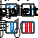

% BandStop

clc; close all; clear all;

M=36;
N=2*M+1;
tw=750;
Fs=16000;
Ts=1/Fs;
fp1=3000+tw/2;
fp2=2000-tw/2;
n=-M:M;

w=window(@hamming,N);

wp1=2*pi*fp1;
wp2=2*pi*fp2;

h1=zeros(1,N);
h1=sin(wp1.*n.*Ts)./(n*pi);
h1(round(length(h1)/2))=wp1*Ts/pi;

h2=zeros(1,N);
h2=sin(wp2.*n.*Ts)./(n*pi);
h2(round(length(h2)/2))=wp2*Ts/pi;

h=0-(h1-h2);
h(round(length(h)/2))=1-(wp1*Ts/pi-wp2*Ts/pi);
h=w'.*h;

N=20480;
Y=abs(fft(h,N));

f=0:Fs/(N-1):Fs;

figure;

subplot(2,2,1)
plot(f,Y);
title('Magnitude Response of the BSF')
axis([0 5000,0 1.1]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on

subplot(2,2,2)
plot(f,Y);
title('Passband ripple of the BSF')
axis([0 5000,0.99 1.01]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on;

subplot(2,2,3)
plot(f,Y);
title('Stopband ripple of the BSF')
axis([0 5000, 0 0.01]);
xlabel('f(Hz)');
ylabel('|H(f)|');
grid on;

subplot(2,2,4)
plot(f,Y); 
title('Transition width of the BSF')
hold on;
plot([2000-750, 2000-750], [0, 1], '-r');
plot([2000, 2000], [0, 1], '-r');
plot([3000+750, 3000+750], [0, 1], '-r');
plot([3000, 3000], [0, 1], '-r');
axis([0 5000,0 1.1]);
xlabel('f(Hz)'); 
ylabel('|H(f)|');
grid on;
hold off;